**ICPC Performance Evaluation Results**

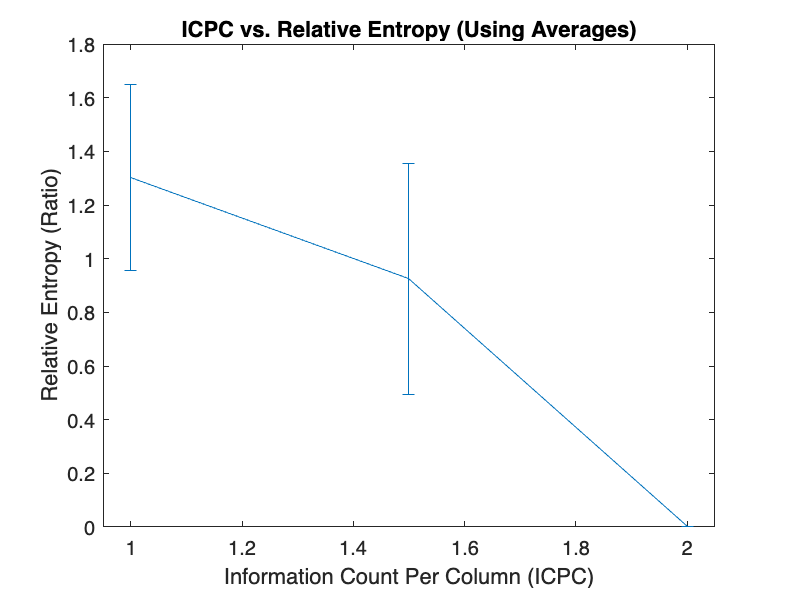

clear;
clf;

% Information Count Per Column Evalution
ICPC = [1 1.5 2]; 

% Data Obtained for Sequences 11-40
relative_entropy = [0.308598315019951 2.910548977605476 0.37127027682450814 0.5649130125672527 1.4706071494692283 0.9801806863906379 3.327905281201462 0.5926521173095973 0.49369821680875814 2.006955052770643;
0.19911616967794976 0.29554518242314426 0.6809791276522268 2.8842714307536044 0.14510039660515092 0.1530874677078425 0.2979177992518275 0.3141308386380971 4.002299651114092 0.28384897030380046 
0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0];
overlapping_positions = [0.8 0.15 0.6 0.9 0.6 0.3 0 0.5 0.8 0.4375; 
    0.9 0.9 0.9 0.0 0.9 1.0 0.8 1.0 0.0 0.9; 
    1.0 1.0 1.0 1.0 1.0 1.0 1.0 1.0 1.0 1.0];
runtime = [1702.606399 1669.999 1712.440967 1651.690985 1702.373904 1663.632901 1700.211277 1647.191287 1697.546032 1638.841142; 
    1712.529088 1660.951561 1705.78973 1666.89484 1719.72566 1644.672286 1700.951843 1644.63764 1706.70388 1646.595236; 
    1686.585896 1635.313428 1642.989935 1694.156565 1648.455053 1707.165828 1652.43143 1707.605279 1672.049162 1720.915796];

relative_entropy_averages_mean = [mean(relative_entropy(1,:)) mean(relative_entropy(2,:)) mean(relative_entropy(3,:))];
relative_entropy_averages_sum = [sum(relative_entropy(1,:)) sum(relative_entropy(2,:)) sum(relative_entropy(3,:))];
overlapping_positions_averages = [mean(overlapping_positions(1,:)) mean(overlapping_positions(2,:)) mean(overlapping_positions(3,:))];
runtime_averages = [mean(runtime(1,:)) mean(runtime(2,:)) mean(runtime(3,:))];

err1 = [std(relative_entropy(1,:)/sqrt(10)) 
    std(relative_entropy(2,:)/sqrt(10)) 
    std(relative_entropy(3,:)/sqrt(10))];
err2 = [std(overlapping_positions(1,:)/sqrt(10)) 
    std(overlapping_positions(2,:)/sqrt(10)) 
    std(overlapping_positions(3,:)/sqrt(10))];
err3 = [std(runtime(1,:)/sqrt(10)) 
    std(runtime(2,:)/sqrt(10)) 
    std(runtime(3,:)/sqrt(10))];

% Graph ICPC vs. Relative Entropy
figure(1)
errorbar(ICPC, relative_entropy_averages_mean, err1)
xlabel("Information Count Per Column (ICPC)");
ylabel("Relative Entropy (Ratio)");
title("ICPC vs. Relative Entropy (Using Averages)");
xlim([.95, 2.05]);

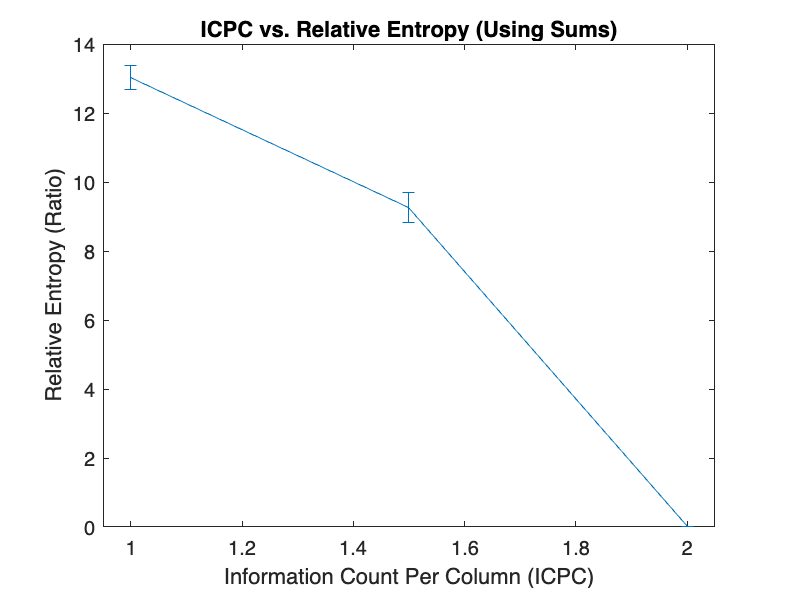


figure(2)
errorbar(ICPC, relative_entropy_averages_sum, err1)
xlabel("Information Count Per Column (ICPC)");
ylabel("Relative Entropy (Ratio)");
title("ICPC vs. Relative Entropy (Using Sums)");
xlim([.95, 2.05]);

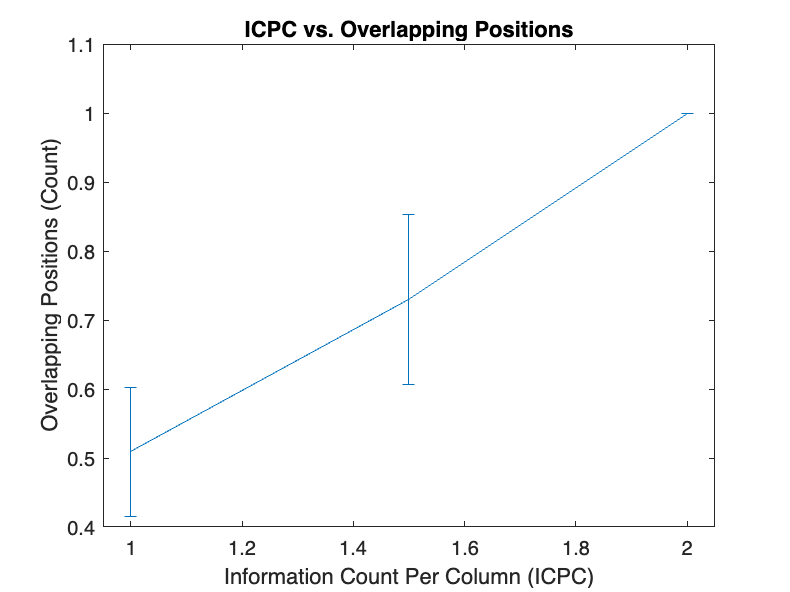


% Graph ICPC vs. Overlapping Positions
figure(3)
errorbar(ICPC, overlapping_positions_averages, err2)
xlabel("Information Count Per Column (ICPC)");
ylabel("Overlapping Positions (Count)");
title("ICPC vs. Overlapping Positions");
xlim([.95, 2.05]);
ylim([0.40, 1.10]);

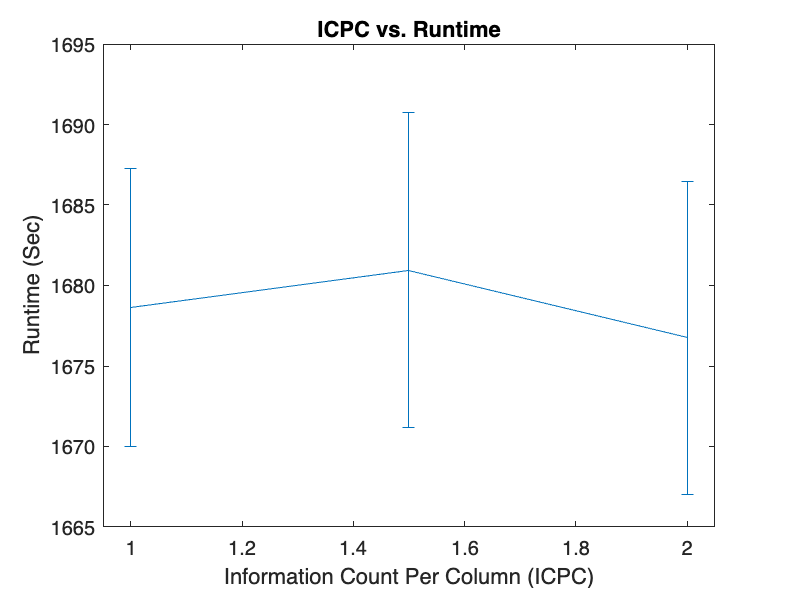


% Graph ICPC vs. Runtime
figure(4)
errorbar(ICPC, runtime_averages, err3)
xlabel("Information Count Per Column (ICPC)");
ylabel("Runtime (Sec)");
title("ICPC vs. Runtime");
xlim([.95, 2.05]);

**ML Performance Evaluation Results**

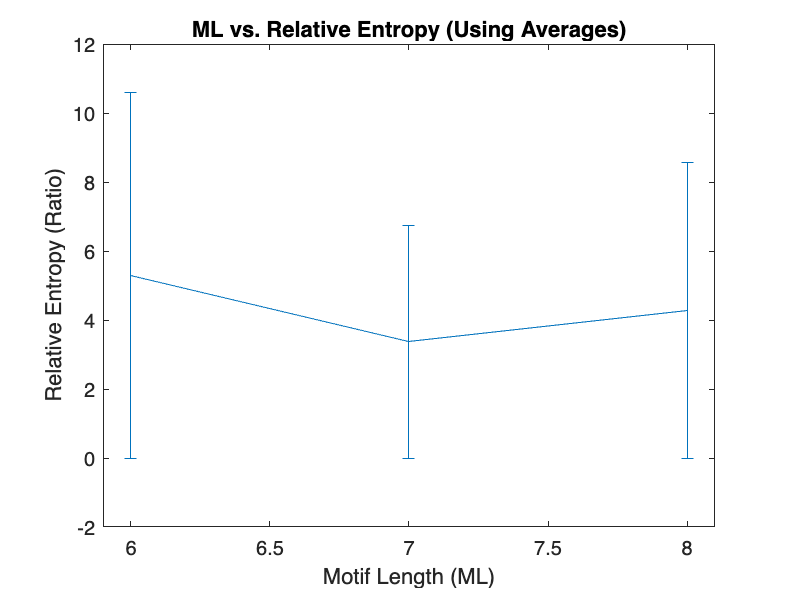

clear;
clf;

% Motif Length Evalution
ML = [6 7 8];

% Data Obtained for Sequences 41-70
relative_entropy = [53.00396770165933 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0;
0.0 0.0 0.0 33.75048590665982 0.0 0.0 0.0 0.0 0.0 0.0;
42.897695829207926 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0];
overlapping_positions = [0.3333333333333333 0.9 0.9 1.0 0.8 1.0 1.0 0.9 1.0 1.0;
    1.0 1.0 1.0 0.05714285714285714 1.0 1.0 1.0 1.0 1.0 0.9;
    0.7875 1.0 1.0 1.0 1.0 1.0 1.0 1.0 1.0 1.0];
runtime = [1290.350055 1292.089393 1295.769379 1294.976419 1300.410946 1299.777012 1291.159513 1296.536561 1296.036344 1307.919375;
1436.152831 1429.940283 1455.356786 1450.545987 1454.4004 1451.248238 1425.362705 1423.92342 1425.52113 1421.846192;
1632.982288 1643.036399 1635.172377 1641.75447 1617.321401 1624.835582 1618.575848 1617.770567 1639.304654 1648.556134];

relative_entropy_averages_mean = [mean(relative_entropy(1,:)) mean(relative_entropy(2,:)) mean(relative_entropy(3,:))];
relative_entropy_averages_sum = [sum(relative_entropy(1,:)) sum(relative_entropy(2,:)) sum(relative_entropy(3,:))];
overlapping_positions_averages = [mean(overlapping_positions(1,:)) mean(overlapping_positions(2,:)) mean(overlapping_positions(3,:))];
runtime_averages = [mean(runtime(1,:)) mean(runtime(2,:)) mean(runtime(3,:))];

err1 = [std(relative_entropy(1,:)/sqrt(10)) 
    std(relative_entropy(2,:)/sqrt(10)) 
    std(relative_entropy(3,:)/sqrt(10))];
err2 = [std(overlapping_positions(1,:)/sqrt(10)) 
    std(overlapping_positions(2,:)/sqrt(10)) 
    std(overlapping_positions(3,:)/sqrt(10))];
err3 = [std(runtime(1,:)/sqrt(10)) 
    std(runtime(2,:)/sqrt(10)) 
    std(runtime(3,:)/sqrt(10))];

% Graph ML vs. Relative Entropy
figure(1)
errorbar(ML, relative_entropy_averages_mean, err1)
xlabel("Motif Length (ML)");
ylabel("Relative Entropy (Ratio)");
title("ML vs. Relative Entropy (Using Averages)");
xlim([5.9, 8.1]);

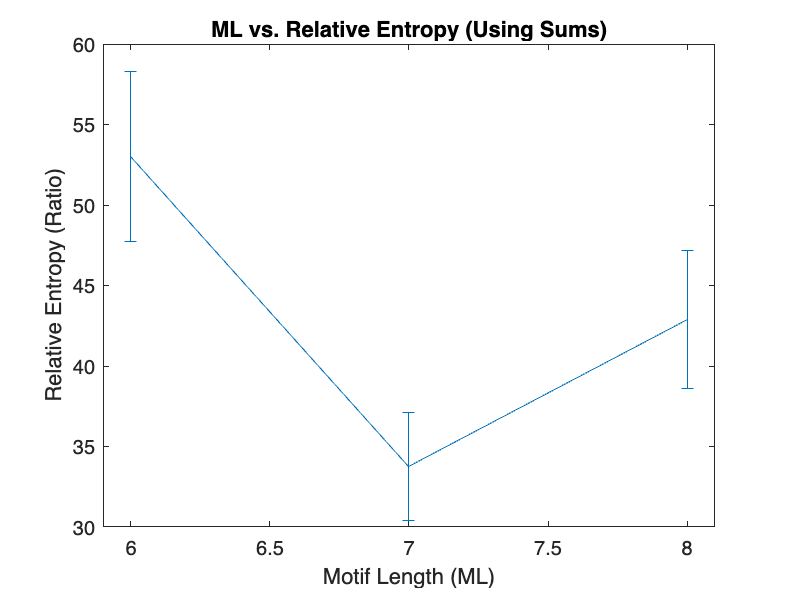


figure(2)
errorbar(ML, relative_entropy_averages_sum, err1)
xlabel("Motif Length (ML)");
ylabel("Relative Entropy (Ratio)");
title("ML vs. Relative Entropy (Using Sums)");
xlim([5.9, 8.1]);

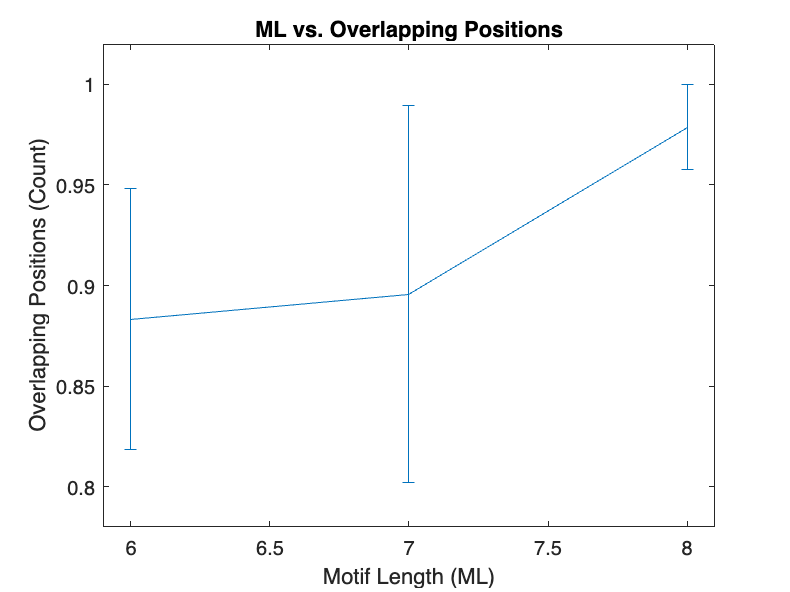


% Graph ML vs. Overlapping Positions
figure(3)
errorbar(ML, overlapping_positions_averages, err2)
xlabel("Motif Length (ML)");
ylabel("Overlapping Positions (Count)");
title("ML vs. Overlapping Positions");
xlim([5.9, 8.1]);
ylim([0.78, 1.02]);

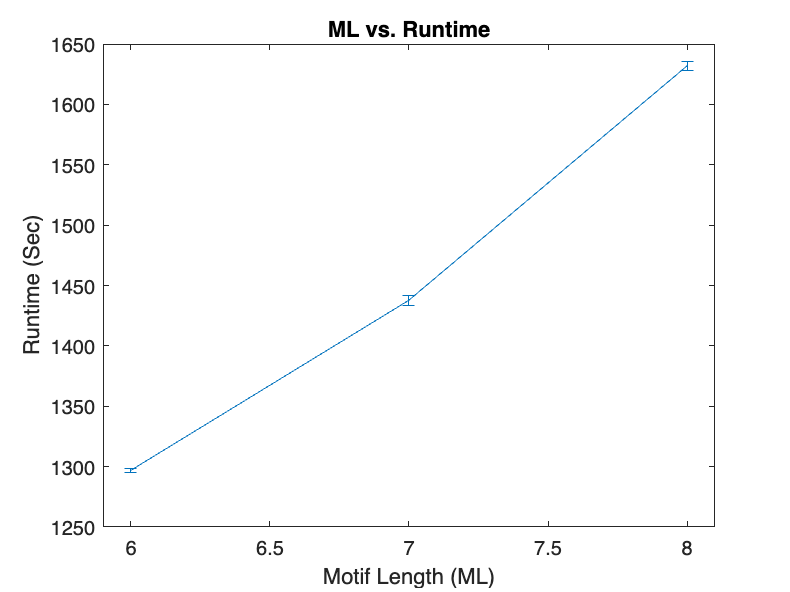


% Graph ML vs. Runtime
figure(4)
errorbar(ML, runtime_averages, err3)
xlabel("Motif Length (ML)");
ylabel("Runtime (Sec)");
title("ML vs. Runtime");
xlim([5.9, 8.1]);

**SC Performance Evaluation Results**

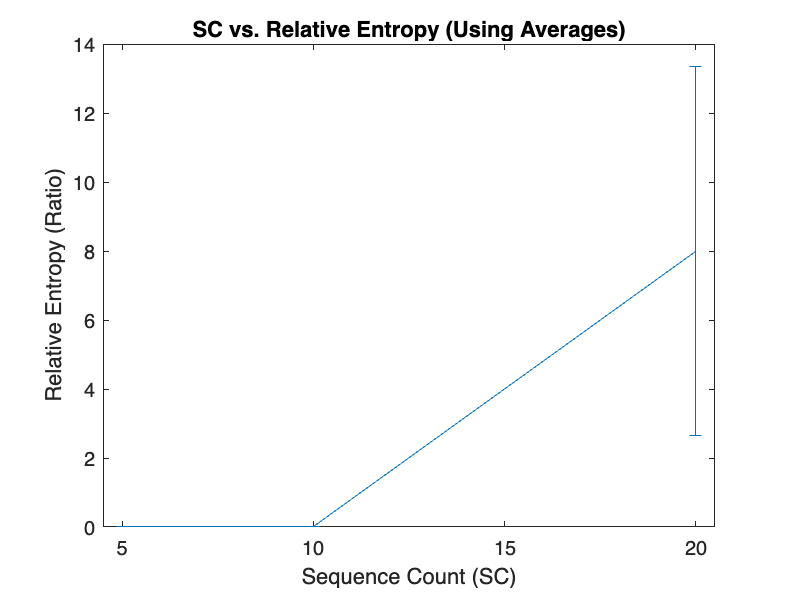

clear;
clf;

% Sequence Count Evalution
SC = [5 10 20];

% Data Obtained for Sequences 71-100
relative_entropy = [0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0;
0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0;
43.29038556545988 0.0 0.0 0.0 0.0 0.0 0.0 0.0 36.664008947448465 0.0];
overlapping_positions = [1.0 1.0 1.0 0.8 1.0 1.0 1.0 1.0 1.0 1.0;
    1.0 0.9 1.0 1.0 1.0 1.0 1.0 1.0 1.0 1.0;
    0.875 1.0 0.95 1.0 1.0 1.0 1.0 1.0 0.7875 1.0];
runtime = [1614.316687 1595.164351 1590.389524 1594.980486 1600.966199 1589.718613 1572.106135 1585.096935 1596.443039 1575.789781;
1613.293196 1613.13514 1616.35466 1613.283628 1611.679354 1635.489338 1643.869715 1626.825532 1616.749355 1617.319969;
1715.241046 1689.025369 1692.545757 1691.607113 1724.632707 1691.283721 1678.313524 1688.345151 1713.227043 1683.007926];

relative_entropy_averages_mean = [mean(relative_entropy(1,:)) mean(relative_entropy(2,:)) mean(relative_entropy(3,:))];
relative_entropy_averages_sum = [sum(relative_entropy(1,:)) sum(relative_entropy(2,:)) sum(relative_entropy(3,:))];
overlapping_positions_averages = [mean(overlapping_positions(1,:)) mean(overlapping_positions(2,:)) mean(overlapping_positions(3,:))];
runtime_averages = [mean(runtime(1,:)) mean(runtime(2,:)) mean(runtime(3,:))];

err1 = [std(relative_entropy(1,:)/sqrt(10)) 
    std(relative_entropy(2,:)/sqrt(10)) 
    std(relative_entropy(3,:)/sqrt(10))];
err2 = [std(overlapping_positions(1,:)/sqrt(10)) 
    std(overlapping_positions(2,:)/sqrt(10)) 
    std(overlapping_positions(3,:)/sqrt(10))];
err3 = [std(runtime(1,:)/sqrt(10)) 
    std(runtime(2,:)/sqrt(10)) 
    std(runtime(3,:)/sqrt(10))];

% Graph SC vs. Relative Entropy
figure(1)
errorbar(SC, relative_entropy_averages_mean, err1)
xlabel("Sequence Count (SC)");
ylabel("Relative Entropy (Ratio)");
title("SC vs. Relative Entropy (Using Averages)");
xlim([4.5, 20.5]);

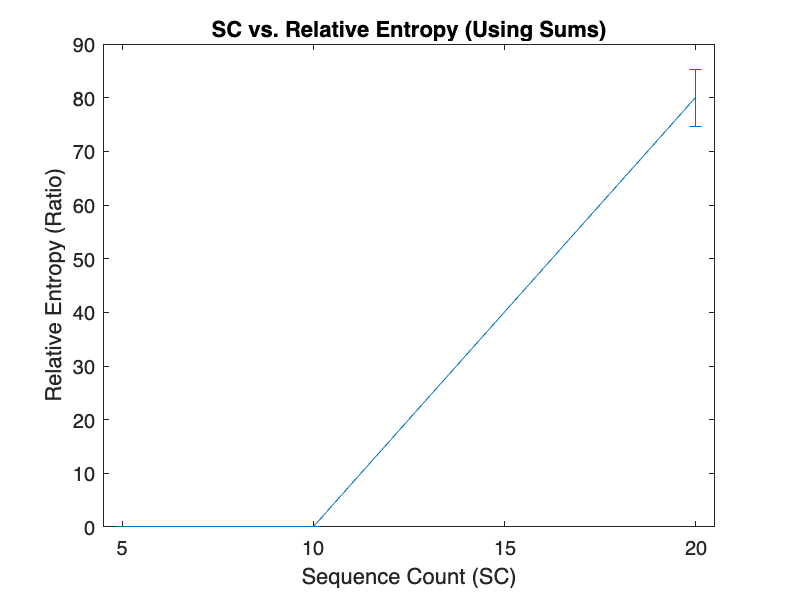


figure(2)
errorbar(SC, relative_entropy_averages_sum, err1)
xlabel("Sequence Count (SC)");
ylabel("Relative Entropy (Ratio)");
title("SC vs. Relative Entropy (Using Sums)");
xlim([4.5, 20.5]);

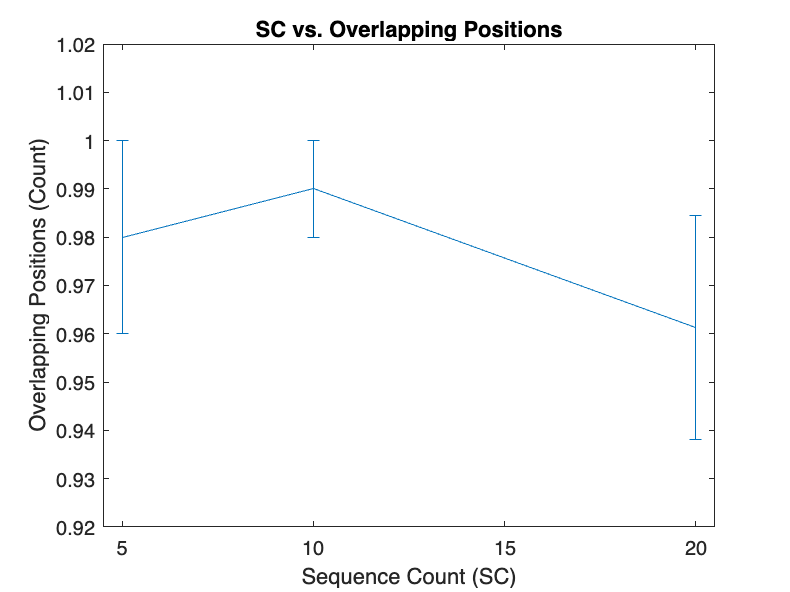


% Graph SC vs. Overlapping Positions
figure(3)
errorbar(SC, overlapping_positions_averages, err2)
xlabel("Sequence Count (SC)");
ylabel("Overlapping Positions (Count)");
title("SC vs. Overlapping Positions");
xlim([4.5, 20.5]);
ylim([0.92, 1.02]);

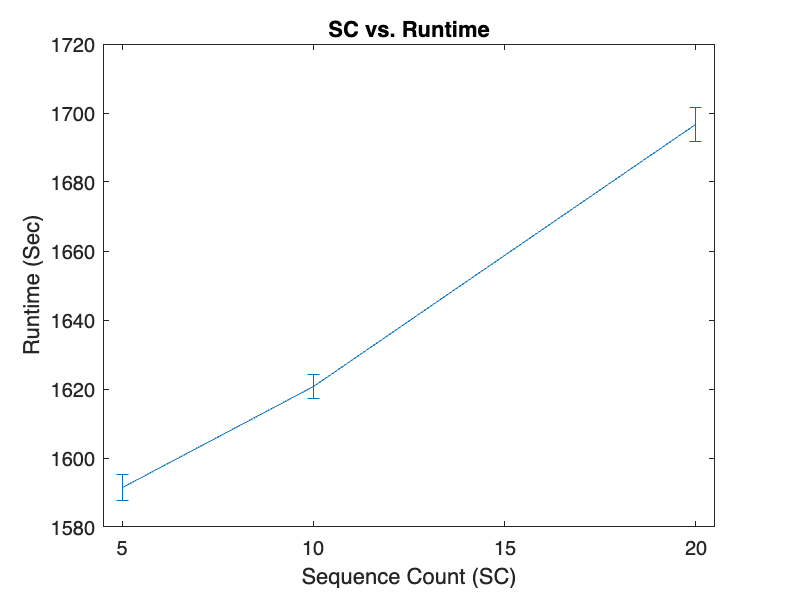


% Graph SC vs. Runtime
figure(4)
errorbar(SC, runtime_averages, err3)
xlabel("Sequence Count (SC)");
ylabel("Runtime (Sec)");
title("SC vs. Runtime");
xlim([4.5, 20.5]);